## **Module:** Digital Signal Processing (DIG5111)

**Student ID:** [24133110]

## Subtractive Synthesiser

## Abstract

This Live Script demonstrates the design and evaluation of a monophonic digital synthesiser voice. A combination of oscillator types, including the since, sawtooth, and a frequency modulation carrier-modulator pair, are implemented along with an ADSR amplitude envelope, Low-frequency oscillator (LFO) modulation, and digital filtering.

Through the use of time-domain and frequency domain methods, the system is analysed to assess how synthesis and filtering choices influence harmonic structure and spectral behaviour.

## Problem Statement & Requirements

## Method Selection & Theory

## Implementation

## Results

## Comparative Study

## Error Analysis & Limitations

## Conclusions & Recommendations

## AI Use Declaration

## Reproducibility cell

fs = 44100;              % sample rate
T = 2;                   % duration (seconds)
t = 0:1/fs:T-1/fs;
f0 = 220; 
                         % fundamental frequency
y = sin(2*pi*f0*t);
y = y / max(abs(y));

player = audioplayer(y, fs); % create audio player object
play(player); % play the sound


sine = sin(2*pi*f0*t);

saw = sawtooth(2*pi*f0*t);

square_wave = square(2*pi*f0*t);

fc = 220;     % carrier
fm = 110;     % modulator
I = 5;        % modulation index

fm_signal = sin(2*pi*fm*t);
fm_synth = sin(2*pi*fc*t + I*fm_signal);

attack = 0.1;
decay = 0.2;
sustain_level = 0.6;
release = 0.3;

env = zeros(size(t));

A = round(attack*fs);
D = round(decay*fs);
R = round(release*fs);
S = max(0, length(t) - (A+D+R));

env(1:A) = linspace(0,1,A);
env(A+1:A+D) = linspace(1,sustain_level,D);
env(A+D+1:A+D+S) = sustain_level;
env(end-R+1:end) = linspace(sustain_level,0,R);

signal = saw .* env;

lfo_freq = 5;
lfo = 0.5*(1 + sin(2*pi*lfo_freq*t)); % 0–1 range

modulated = signal .* lfo;

vibrato = 5 * sin(2*pi*5*t); % 5 Hz LFO
vib_signal = sin(2*pi*(f0 + vibrato).*t);

fc = 1000;
[b,a] = butter(4, fc/(fs/2));

filtered_iir = filter(b,a,modulated);


N = 100;
b_fir = fir1(N, fc/(fs/2));

filtered_fir = filter(b_fir,1,modulated);

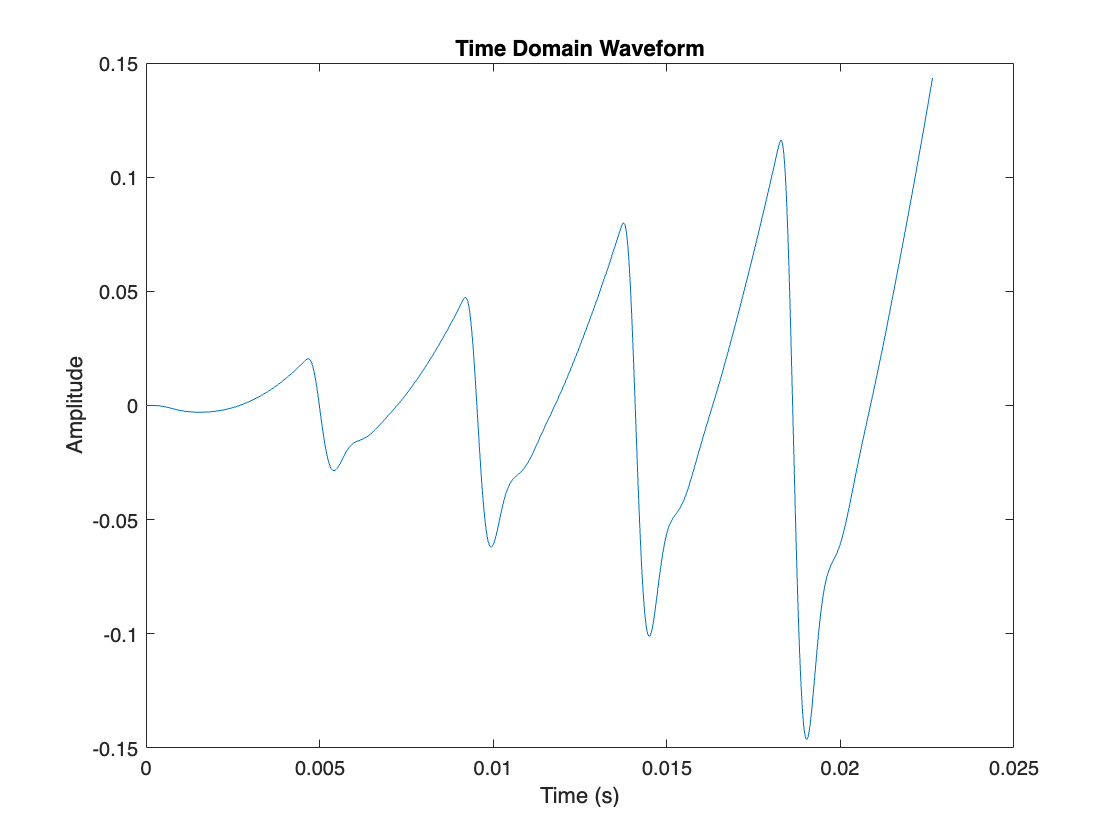

figure;
plot(t(1:1000), filtered_iir(1:1000));
title('Time Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude');

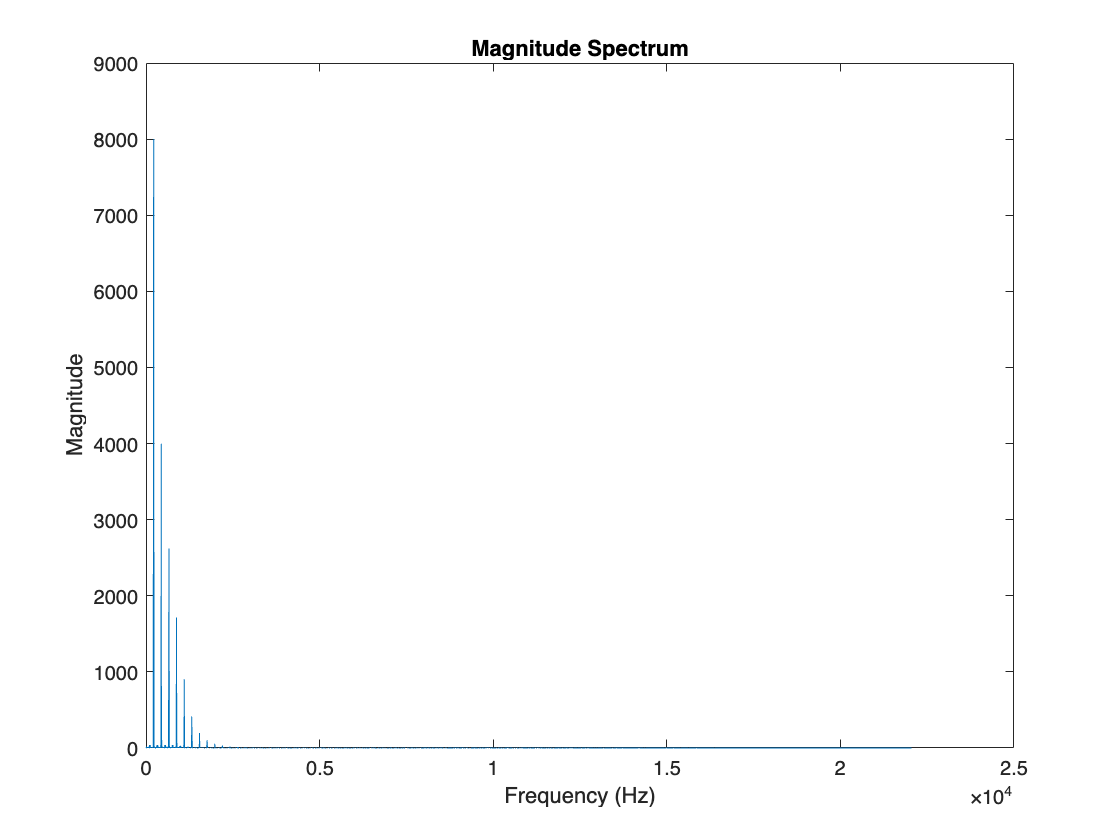

NFFT = length(filtered_iir);
X = abs(fft(filtered_iir));
f = (0:NFFT-1)*(fs/NFFT);

figure;
plot(f(1:NFFT/2), X(1:NFFT/2));
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

## Conclusion